%объявление переменных
%syms x xp yp y m f a b l p xs ys xf yf ;

% задание начальных значений
xp = -2;
yp = -2;
a = 2;
b = 1;
c = sqrt(a^2-b^2);
xS = -c;
xF = c;

plot(xS, 0, 'or');
hold on
plot(xF, 0, 'or');
hold on
fi = 0:0.1:2*pi;
XE = a*cos(fi);
YE = b*sin(fi);
plot(XE, YE, '-k');
hold on
plot(xp, yp, 'xr');

% поиск лямбы в уравнении Лагранжа
p = [(a^6*b^6-(xp^2*b^6+yp^2*a^6)) (2*(a^4*b^6+a^6*b^4-xp^2*b^4+yp^2*a^4)) ((a^4+4*a^2*b^2+b^4)*a^2*b^2-(yp^2*a^2+xp^2*b^2)) (2*a*a*b*b*(a*a+b*b)) (a*a*b*b)];
f = roots(p);
disp(f);

   1.8100 + 0.0000i
  -0.1253 + 0.2655i
  -0.1253 - 0.2655i
  -0.1308 + 0.0000i




X = [];
Y = [];


% отбор подходящей лямбды - вещественной, большей нуля
for c = 1:4 % поскольку уравнение 4й степени, всегда будет не более 4х лямбд
    
    if ( isreal(f(c))) %проверка на отсутствие мнимой части и положительность
        l = f(c);
        disp(f(c));
        x = a^2*xp/(a*a+l);
        y = b^2*yp/(b*b+l);
        X = [X x];
        Y = [Y y];
     
    end
end

    1.8100

   -0.1308




X

X =    -1.3769   -2.0676


Y

Y =    -0.7117   -2.3010


for j = 1:size(X, 2)
    D(j) = (X(j) - xp)^2 + (Y(j) - yp)^2;
end

D

D =     2.0478    0.0952



[Dmax Jmax] = max(D)

Dmax = 2.0478

Jmax = 1

x = X(Jmax)

x = -1.3769

y = Y(Jmax)

y = -0.7117

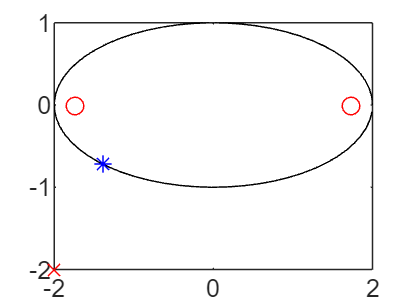

plot (x, y, '*b');

return;
%находим координаты нашей точки (х;y)
%x = a^2*xp/(a*a+l);
%y = b^2*yp/(b*b+l);
%disp(x);
%disp(y);

%построение траектории 

line([xS 0] , [x y],'Color','green','LineStyle','--')
hold on
line([x y] , [xF 0],'Color','red','LineStyle','--')

%fplot(f, [-10,10])

 